# Classification of XOR problem with RBFN networks

The exercise demonstrates an application of various Radial Basis Function based neural networks for solving the XOR problem. XOR or "exclusive or" problem is a classical problem in neural networks research that consists of solving a nonlinear "exclusive or" classification of 4 clusters of data into 2 output classes (class A and class B). 

Four clusters of data (A1, A1, B1, B2) are defined in 2-dimensional input space. Samples of 'A' and 'B' classes represent XOR classification problem. 

The task is to define a neural network (RBFN, PNN, GRNN) for solving the XOR problem. 

The last section demonstrates the Radial Basis Function Network, additionally trained by Bayesian regularization backpropagation, which provides the basis for good generalization.

At the end of the script, functions 'Plot data' and 'Plot classification results' are defined and used in all sections to plot data and classification results.

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Generate data

Generate 2-dimensional data representing XOR problem. 

close all, clear, clc, format compact

**Create input data**

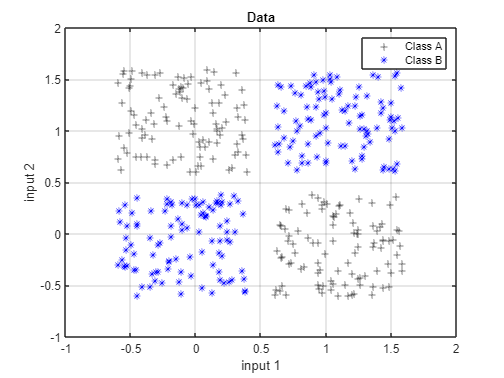

Nclass =100; % number of samples of each class
offset =0.6; % offset between classes

 

% define 2 groups of input data
a = [rand(1,Nclass)-offset rand(1,Nclass)+offset;
     rand(1,Nclass)+offset rand(1,Nclass)-offset];
b = [rand(1,Nclass)+offset rand(1,Nclass)-offset;
     rand(1,Nclass)+offset rand(1,Nclass)-offset];

% call custom function to plot data
plot_data(a,b);

**Define output coding**

% define output coding for XOR problem, encode classes A and B
A = -1;
B =  1;

**Prepare inputs and outputs for network training**

% define inputs (combine samples from all four classes)
P = [a b];

% define targets
T = [repmat(A,1,length(a)) repmat(B,1,length(b))];

## Exact RBFN

Exact Radial Basis Function Network. MATLAB function 'newrbe' is used to construct the exact RBFN model where each data sample represents one RBF center of the network.

% network settings
spread = 2; % spread constant

 

% create a neural network
net    = newrbe(P,T,spread);

The 'Rank deficient' warning is typical for training exact RBFN models with many samples. Display the number of RBF centers.

% the number of RBF centers
number_of_RBF_centers = length(net.iw{1})

number_of_RBF_centers = 400

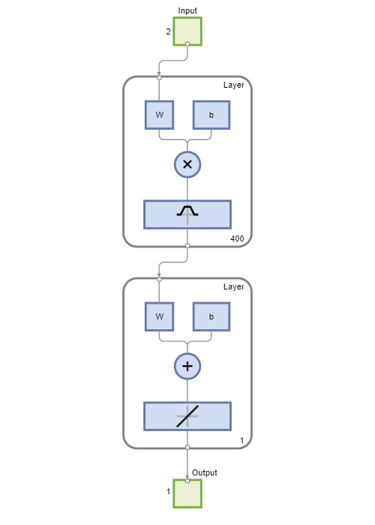

% view network
view(net)

% simulate a network on training data
Y = net(P);

% calculate classification accuracy
classification_accuracy = length(find(T.*Y > 0))/length(T)

classification_accuracy = 1

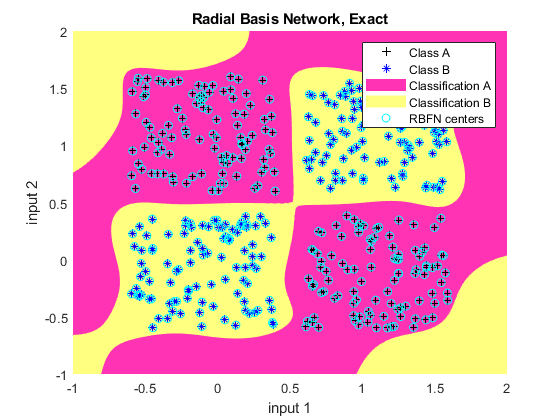

% plot results
plot_classification_results(a,b,net);

Notice good decision boundaries in the area of training samples and often strange segmentation of the space outside of this area (extrapolation regions).

## RBFN

Improved Radial Basis Function Network. MATLAB function 'newrb' is used to construct the improved RBFN model with a considerably reduced number of RBF centers.

NEWRB, neurons = 0, MSE = 1
NEWRB, neurons = 5, MSE = 0.305465
NEWRB, neurons = 10, MSE = 0.204705
NEWRB, neurons = 15, MSE = 0.102087
NEWRB, neurons = 20, MSE = 0.0452549
NEWRB, neurons = 25, MSE = 0.0305524
NEWRB, neurons = 30, MSE = 0.0207343
NEWRB, neurons = 35, MSE = 0.0171847
NEWRB, neurons = 40, MSE = 0.0148582
NEWRB, neurons = 45, MSE = 0.0115948
NEWRB, neurons = 50, MSE = 0.009678


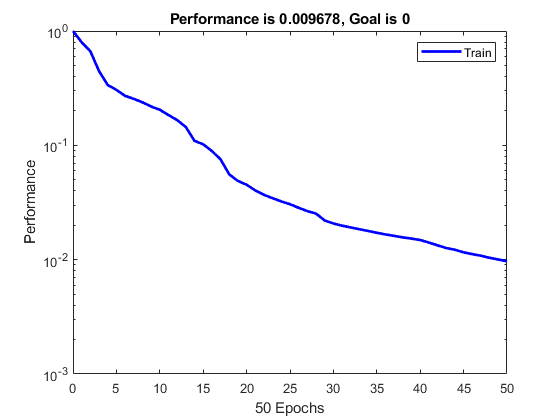

% network settings
spread = 0.3; % spread constant
K      = 50;  % max number of neurons
Ki     = 5; % number of neurons to add between displays
goal   = 0; % performance goal (SSE)

 

% create a neural network
net = newrb(P,T,goal,spread,K,Ki);

Display the number of RBF centers (K) and notice that it is considerably reduced (with respect to exact RBFN).

% the number of RBF centers
number_of_RBF_centers = length(net.iw{1})

number_of_RBF_centers = 50

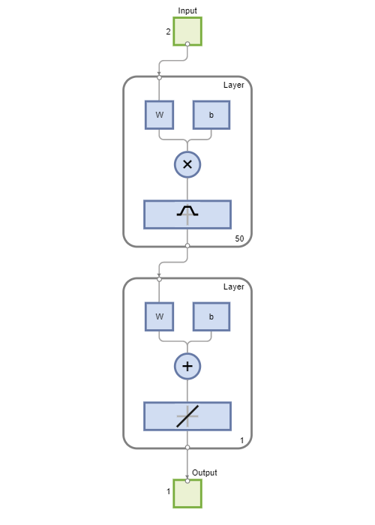

% view network
view(net)

% simulate RBFN on training data
Y = net(P);

% calculate classification accuracy
classification_accuracy = length(find(T.*Y > 0))/length(T)

classification_accuracy = 1

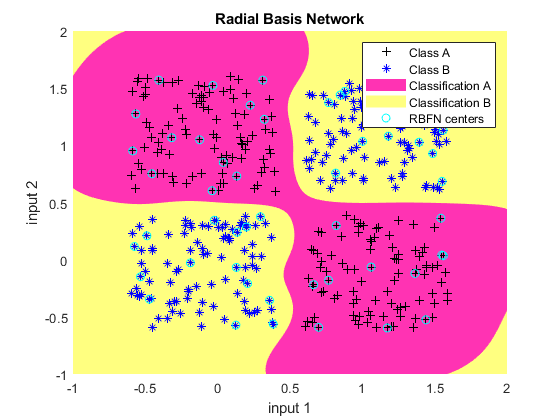

% plot results
plot_classification_results(a,b,net);

Improved RBFN often performs more robust compared to exact RBFN.

## PNN

Probabilistic Neural Network, constructed by using MATLAB function 'newpnn'.

% network settings
spread =0.7; % spread constant

 

% create a neural network
net = newpnn(P,ind2vec(T+2),spread); % T+2: PNN requires different class definitions

Display the number of PNN centers which is the same as the number of training samples.

% the number of RBF centers
number_of_PNN_centers = length(net.iw{1})

number_of_PNN_centers = 400

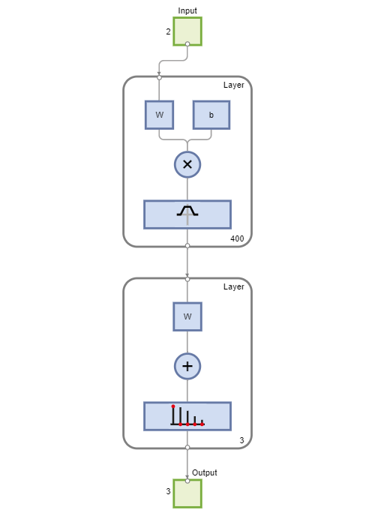

% view network
view(net)

% simulate RBFN on training data
Y = vec2ind(net(P))-2;

% calculate classification accuracy
classification_accuracy = length(find(T.*Y > 0))/length(T)

classification_accuracy = 0.9975

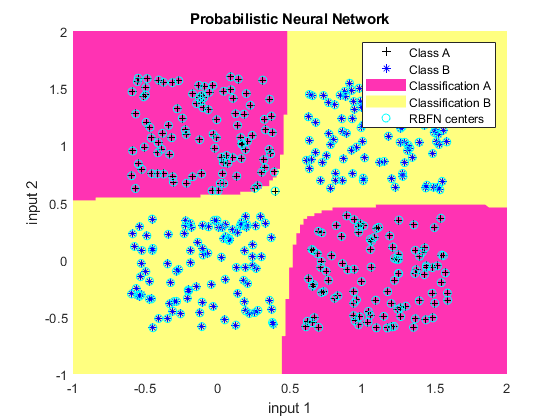

% plot results
plot_classification_results(a,b,net);

Notice that PNN model provides robust decision boundaries with good extrapolation behavior. 

## GRNN

Generalized Regression Neural Network. MATLAB function 'newgrnn' is applied to construct a robust GRNN model.

% network settings
spread = 0.5; % spread constant

 

% create a neural network
net    = newgrnn(P,T,spread);

Display the number of GRNN centers which is the same as the number of training samples.

% the number of RBF centers
number_of_GRNN_centers = length(net.iw{1})

number_of_GRNN_centers = 400

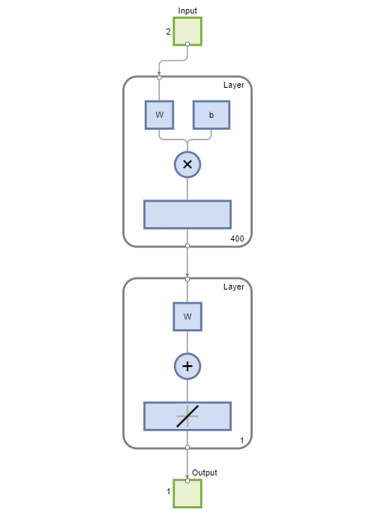

% view network
view(net)

% simulate a network on training data
Y = net(P);

% calculate classification accuracy
classification_accuracy = length(find(T.*Y > 0))/length(T)

classification_accuracy = 0.9975

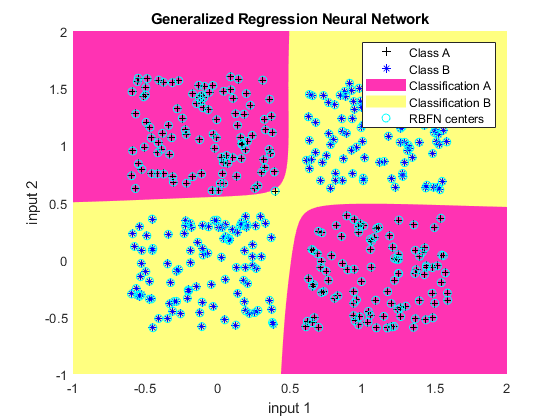

% plot results
plot_classification_results(a,b,net);

Also GRNN model provides robust decision boundaries with good extrapolation behavior. 

## RBFN and Bayesian Regularization

Radial Basis Function Network, additionally trained by Bayesian regularization backpropagation. MATLAB built-in function 'newrb' is used to construct the network which is then trained by 'trainbr' method.

NEWRB, neurons = 0, MSE = 1
NEWRB, neurons = 5, MSE = 0.568766
NEWRB, neurons = 10, MSE = 0.350456
NEWRB, neurons = 15, MSE = 0.199697
NEWRB, neurons = 20, MSE = 0.105231
NEWRB, neurons = 25, MSE = 0.0759548
NEWRB, neurons = 30, MSE = 0.0557391


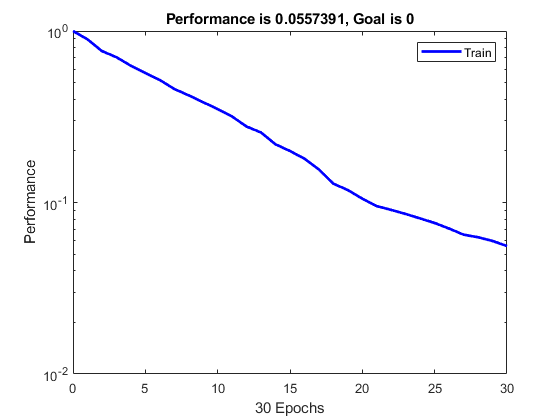

% network settings
spread =0.2; % spread constant
K      =30;  % max number of neurons
Ki     = 5; % number of neurons to add between displays
goal   = 0; % performance goal (SSE)

 

% create a neural network
net    = newrb(P,T,goal,spread,K,Ki);

Display the number of RBF centers (K).

% the number of RBF centers
number_of_RBF_centers = length(net.iw{1})

number_of_RBF_centers = 30

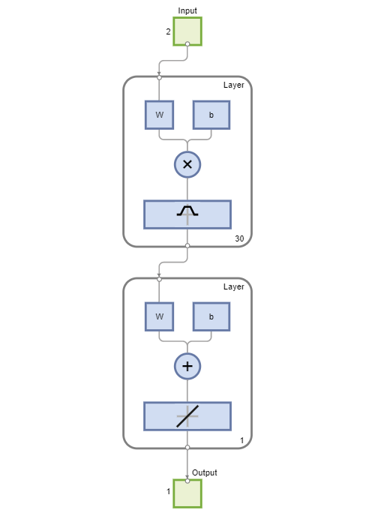

% view network
view(net)

**Retrain a RBFN using Bayesian regularization backpropagation**

% default RBFN spreads 
individual_spreads_initially = net.b{1}

individual_spreads_initially =     4.1628
    4.1628
    4.1628
    4.1628
    4.1628
    4.1628
    4.1628
    4.1628
    4.1628
    4.1628


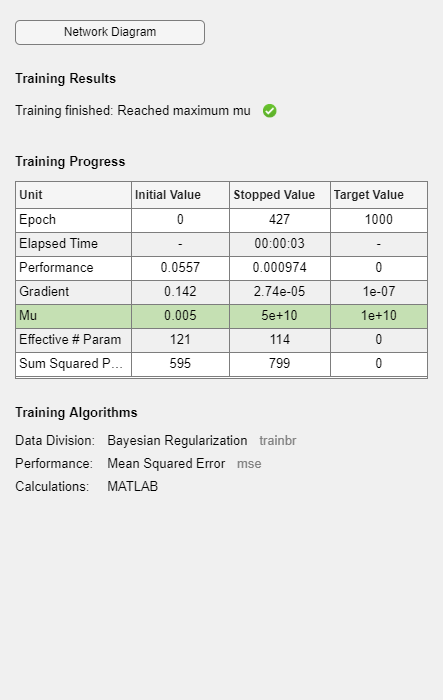

% define custom training function: Bayesian regularization backpropagation
net.trainFcn='trainbr';

% perform Levenberg-Marquardt training with Bayesian regularization
net = train(net,P,T);

% check new RBFN spreads
individual_spreads_after_training = net.b{1}

individual_spreads_after_training =     4.7192
    2.4213
    5.0810
    2.4389
    1.6373
    2.2598
    7.3384
    6.1339
    5.8137
    6.1708


% simulate RBFN on training data
Y = net(P);

% calculate classification accuracy
classification_accuracy = length(find(T.*Y > 0))/length(T)

classification_accuracy = 1

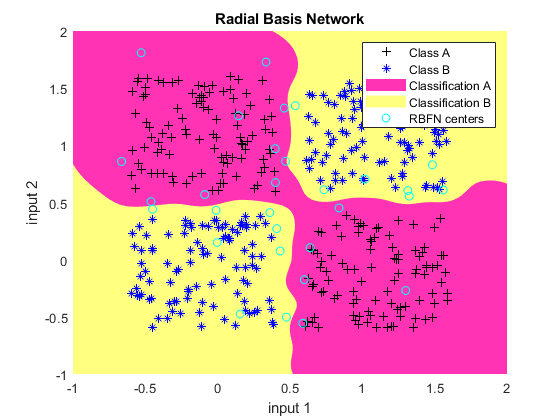

% plot results
plot_classification_results(a,b,net);

Notice the repositioned RBFN centers (not located on training samples) due to retraining using Bayesian regularization backpropagation.

% close all windows
close all force

## PowerPoint presentation

[NN6a_RBFN.pptx](matlab:open('./NN6a_RBFN.pptx'))

## Functions

### **Plot data**

Plotting function for 2-dimensional data representing XOR problem.

function [X,Xtrain,Ytrain] = plot_data(A,B)
  figure
  plot(A(1,:),A(2,:),'k+',B(1,:),B(2,:),'b*')
  grid on, hold on
  xlabel('input 1')
  ylabel('input 2')
  legend('Class A','Class B')
  title('Data')
end

### **Plot classification results**

Function for plotting the classification decision boundaries (provided by model 'net') in the space of 2-dimensional data representing XOR problem.

function [X,Xtrain,Ytrain] = plot_classification_results(A,B,net)
  % generate a grid
  span    = -1:.025:2;
  [P1,P2] = meshgrid(span,span);
  pp      = [P1(:) P2(:)]';

  % simualte neural network on a grid
  aa      = sim(net,pp);
  if strcmp(net.name,'Probabilistic Neural Network') % calculate response for PNN
    aa    = vec2ind(aa)-1.5; % convert
  end
  
  % plot data
  plot_data(A,B);

  % plot classification regions based on MAX activation
  ma = mesh(P1,P2,reshape(-aa,length(span),length(span))-5);
  mb = mesh(P1,P2,reshape( aa,length(span),length(span))-5);
  set(ma,'facecolor',[1 0.2 .7],'linestyle','none');
  set(mb,'facecolor',[1 1.0 .5],'linestyle','none');
  view(2)
  
  % Plot RBFN centers
  plot(net.iw{1}(:,1),net.iw{1}(:,2),'co')
  title(net.name)
  legend('Class A','Class B','Classification A','Classification B','RBFN centers')
  drawnow  
end